1️⃣ Cargar datos y sincronizar tiempos

data = readtable('identificacion_motor.csv');

% Convertir tiempos relativos
t_cmd = data.t_cmd - data.t_cmd(1);
t_odom = data.t_odom - data.t_odom(1);

u = data.u_right;      % señal de control
y = data.w_right;      % velocidad angular medida
Ts = 0.1;              % tiempo de muestreo (según ESP32)

**2️⃣ Limpieza y sincronización**

En la práctica, `t_cmd` y `t_odom` pueden diferir ligeramente.

Para sincronizar puedes interpolar:

% 1) Eliminar filas no finitas
valid = isfinite(t_cmd) & isfinite(t_odom) & isfinite(u) & isfinite(y);
t_cmd = t_cmd(valid);
t_odom = t_odom(valid);
u = u(valid);
y = y(valid);

% 2) Quitar duplicados y ordenar por tiempo de comando
[t_cmd, idx] = unique(t_cmd, 'stable');
u = u(idx);

% 3) Para t_odom, quitar duplicados también
[t_odom, idxo] = unique(t_odom, 'stable');
y = y(idxo);

% 4) Interpolar y sincronizar: interpola la salida y(t_odom) en los instantes t_cmd
t_common = t_cmd;
y_sync = interp1(t_odom, y, t_common, 'linear', 'extrap');

3️⃣ Creación de objeto de identificación

data_id = iddata(y_sync, u, Ts)

data_id = Time domain data set with 553 samples.
Sample time: 0.1 seconds              
                                      
Outputs      Unit (if specified)      
   y1                                 
                                      
Inputs       Unit (if specified)      
   u1                                 
                                      
Data Properties

**4️⃣ Identificación de la planta**

Modelos recomendados:

- **Primer orden con retardo:** `tfest(data_id, 1, 1)`

- **Segundo orden:** `tfest(data_id, 2)`

- **Modelo discreto ARX:** `arx(data_id, [2 2 1])`

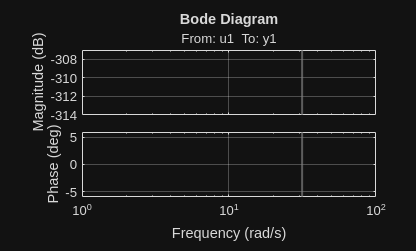

sys1 = tfest(data_id, 1, 1);  % primer orden con retardo
sysz = c2d(sys1, Ts, 'zoh');  % convertir a tiempo discreto
bode(sysz), grid on

**5️⃣ Normalización (opcional)**

Normalizar ayuda si las magnitudes son muy diferentes (por ejemplo, velocidades pequeñas y comandos grandes).

Pero para un motor DC, lo recomendable es **usar datos reales sin normalizar**

y mantener unidades físicas (rad/s y niveles de control ±63).

**6️⃣ PID y PIDF en MATLAB**

MATLAB permite diseñar:

- **PID estándar:** C(s)=Kp+Ki/s+KdsC(s) = K_p + K_i/s + K_d sC(s)=Kp�+Ki�/s+Kd�s

- **PIDF (PID con filtro derivativo):**C(s)=Kp+Ki/s+Kds1+NsC(s) = K_p + K_i/s + \frac{K_d s}{1 + N s}C(s)=Kp�+Ki�/s+1+NsKd�s�donde NNN es el factor de filtrado (reduce ruido en la derivada).

Con `pidtune(sys, 'PIDF')` puedes obtener directamente un controlador discreto:

C = pidtune(sysz, 'PIDF');
Kp = C.Kp

Kp = 0

Ki = C.Ki

Ki = -10.0000

Kd = C.Kd

Kd = 0